clear all;
close all;
clc;

opengl('software');
warning('off')

PS = PLOT_STANDARDS(); % PLOT_STANDARDS defines your color scheme.

% Horizontal abduction trajectory angles
angles = [30, 60, 90];

% Assistance and Resistance levels
conditions = {'AssBassa', 'AssMedia', 'Cinematica', 'Eval', ...
              'ResBassa', 'ResAlta', 'ResMedia', ...
              'ResBassaGauss', 'ResMediaGauss', 'ResAltaGauss', ...
              'senzaESO'};

% Mapping from Italian condition names (as stored originally) to English equivalents
conditionsEng = {'Low Assistance', 'Medium Assistance', 'Passive Kinematics', 'Transparency', ...
                 'Low Resistance', 'High Resistance', 'Medium Resistance', ...
                 'Low Gaussian Resistance', 'Medium Gaussian Resistance', 'High Gaussian Resistance', ...
                 'Without Exo'};

% Muscles engaged in EMG analysis
nameMuscles = {'R.Ant.Deltoid', 'R.Mid.Deltoid', 'R.Post. Deltoid', 'R.Pect. Major', ...
               'R.Upper Trap.', 'R.Middle Trap.', 'R.Lower Trap.', 'R.Biceps Br.', ...
               'R.Med. Triceps', 'R.Lat. Triceps', 'R.Lat.Dorsi', 'R. Serratus Ant.', ...
               'R.Brachiorad', 'R.Flex.Carp.R', 'R.Ext.Carp.Rad.', 'R. Biceps Brevis Br.'};

numMuscles = length(nameMuscles);

## **Data reading and storage**

- **Read c3d file**

datadir = fullfile('C:\Users\mursi\Desktop\S2', 'S2_C3D');

% Structure initialization for storing all C3D data
allData = struct();

% Cycle for all the assistance/resistance conditions
for c = 1:length(conditions)
    condition = conditions{c};
    
    % Cycle for all the trajectory angles
    for a = 1:length(angles)
        angle = angles(a);
        
        % Creation of the file name
        fname = sprintf('%s_%d.c3d', condition, angle);
        
        % Read the .c3d file
        data = readc3d(fullfile(datadir, fname));
        
        % Parameters extraction
        fs = data.Parameter.ANALOG.RATE.data;     
        
        % Store the data in the structure allData
        % The structure is indexed for condition and angle
        allData.(condition).(sprintf('Angle_%d', angle)) = struct('data', data, ...
                                                                  'fs', fs);
    end
end
% Now, you can access to data for a certain condition and angle using:
% allData.<condition>.Angle_<angle>.data, ad esempio: allData.AssBassa.Angle_30.data

- **Read txt file**

datadir = fullfile('C:\Users\mursi\Desktop\S2', 'S2_ASCII');

% Structure initialization for storing all TXT data
allTxtData = struct();

% Cycle for all conditions
for c = 1:length(conditions)
    condition = conditions{c};
    
    % Cycle for all angles
    for a = 1:length(angles)
        angle = angles(a);
        
        % Creation of the file .txt name
        fname = sprintf('%s_%d.txt', condition, angle);
        filepath = fullfile(datadir, fname);

        % Open the file
        fileID = fopen(filepath, 'r');     
        
        % Jump the 1st 4 lines
        for i = 1:4
            fgetl(fileID);
        end

        % Read the rest of the file in a table
        data = readtable(filepath);

        % Close the file
        fclose(fileID);

        % Remove the 1st column that is the time
        data = data(:, 2:17);

        % Set the variables' names with the muscles' ones
        data.Properties.VariableNames = nameMuscles;

        % Samples and time variable
        nsamples = height(data); % Use 'height' instead of 'length' for the tables
        time = (0:(nsamples-1)) / fs;

        % Store data in the structure 'allTxtData'
        allTxtData.(condition).(sprintf('Angle_%d', angle)) = struct('data', data, ...
            'nsamples', nsamples, ...
            'time', time, ...
            'fs', fs);
    end
end

% Now, you can access to data for a certain condition and angle using:
% allTxtData.<condition>.Angle_<angle>.data, ad esempio: allTxtData.AssBassa.Angle_30.data

- **Read MVC data**

% Initialize a row vector for storing MVC values
mvc = zeros(1, numMuscles);

% Load MVC data for each muscle
for i = 1:numMuscles

    fname = sprintf('MVC_E%d.txt', i);
    filepath = fullfile(datadir, fname);

    fileID = fopen(filepath, 'r');

    for j = 1:4
        fgetl(fileID);
    end

    data = readtable(filepath);
        
    fclose(fileID);
    
    data = data(:, 2:17);
    
    data.Properties.VariableNames = nameMuscles;
        
    nsamples = height(data); 
    time = (0:(nsamples-1)) / fs;
    
    % Take the right column (i+1)
    muscleData = data{:, i};
    
    % Take the max of the interested column (uV)
    mvc(i) = max(muscleData);
end

## Raw Data Plot

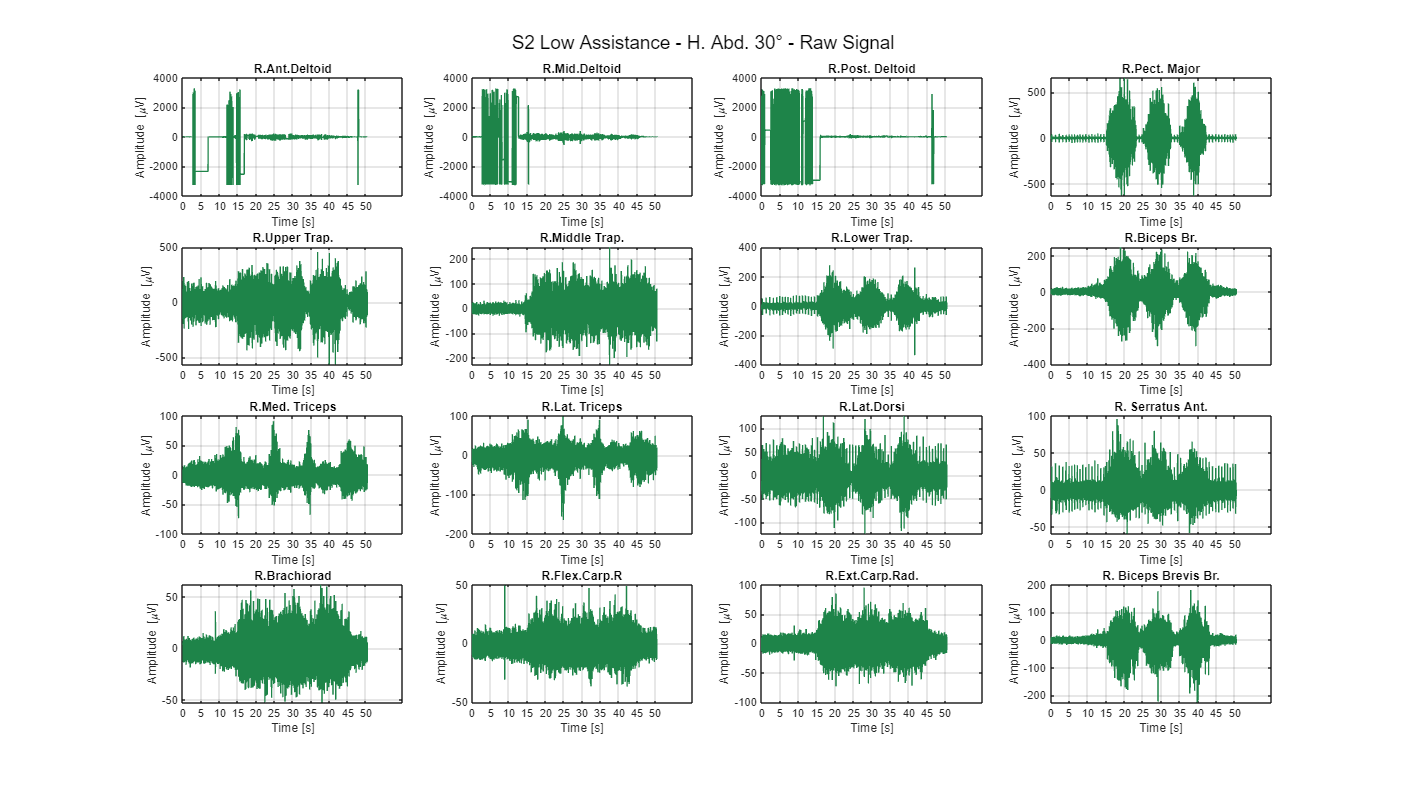

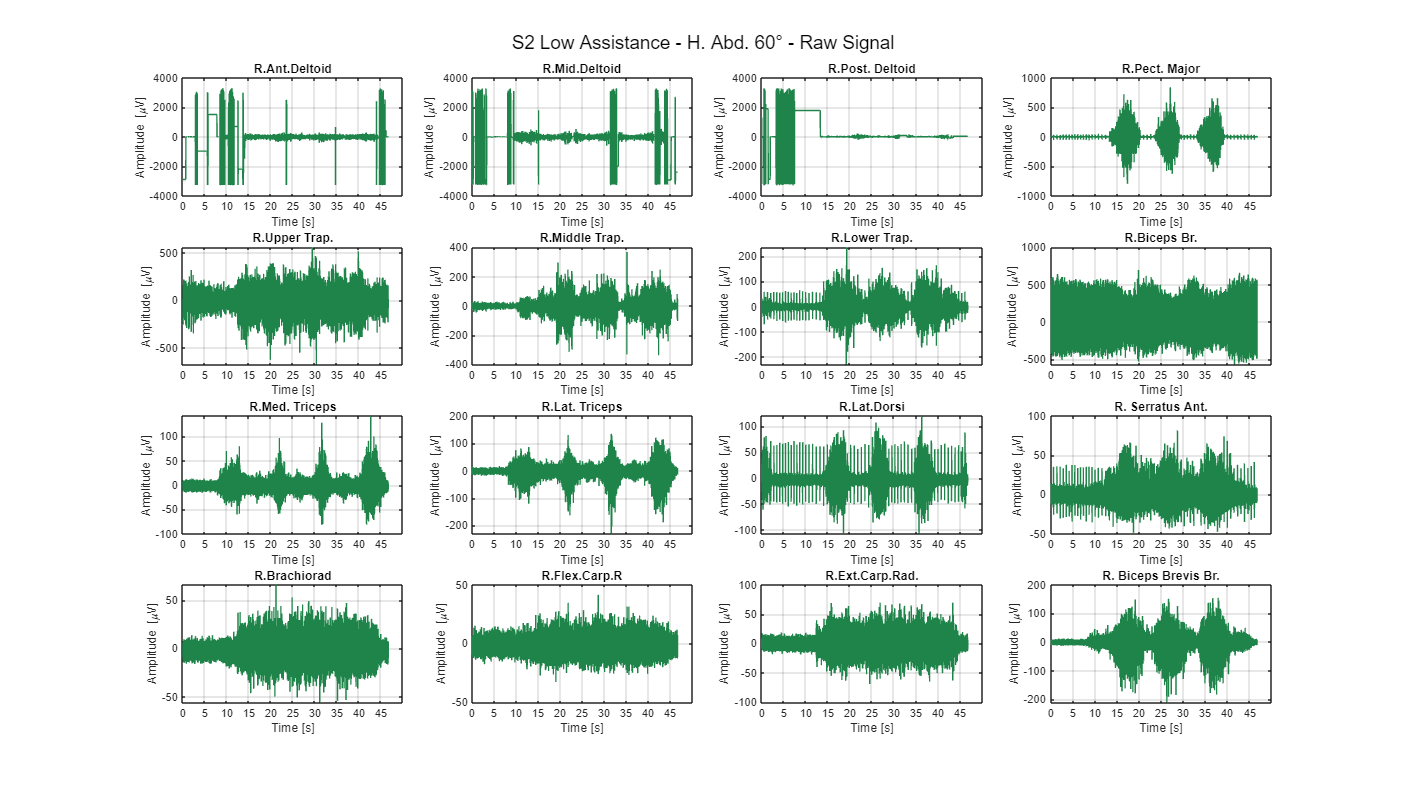

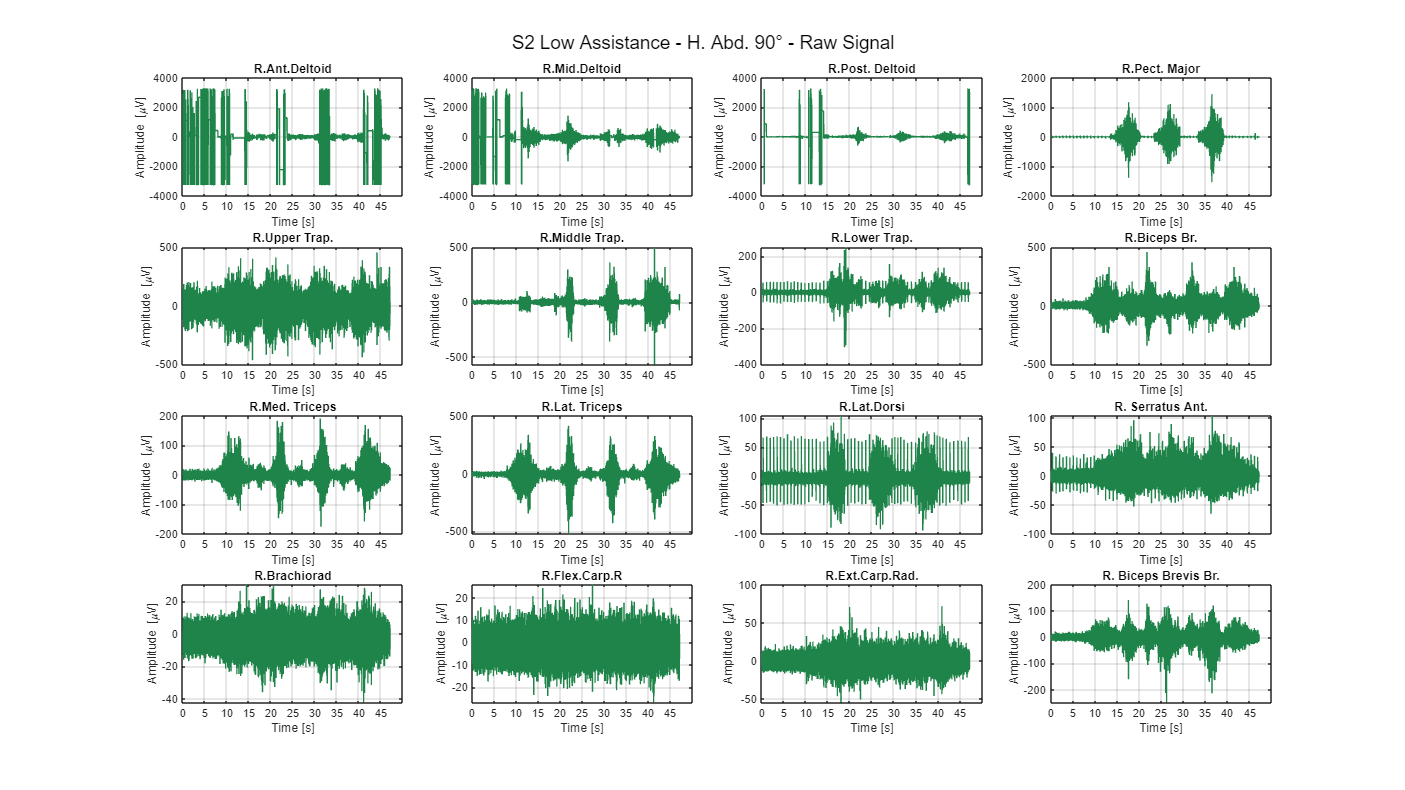

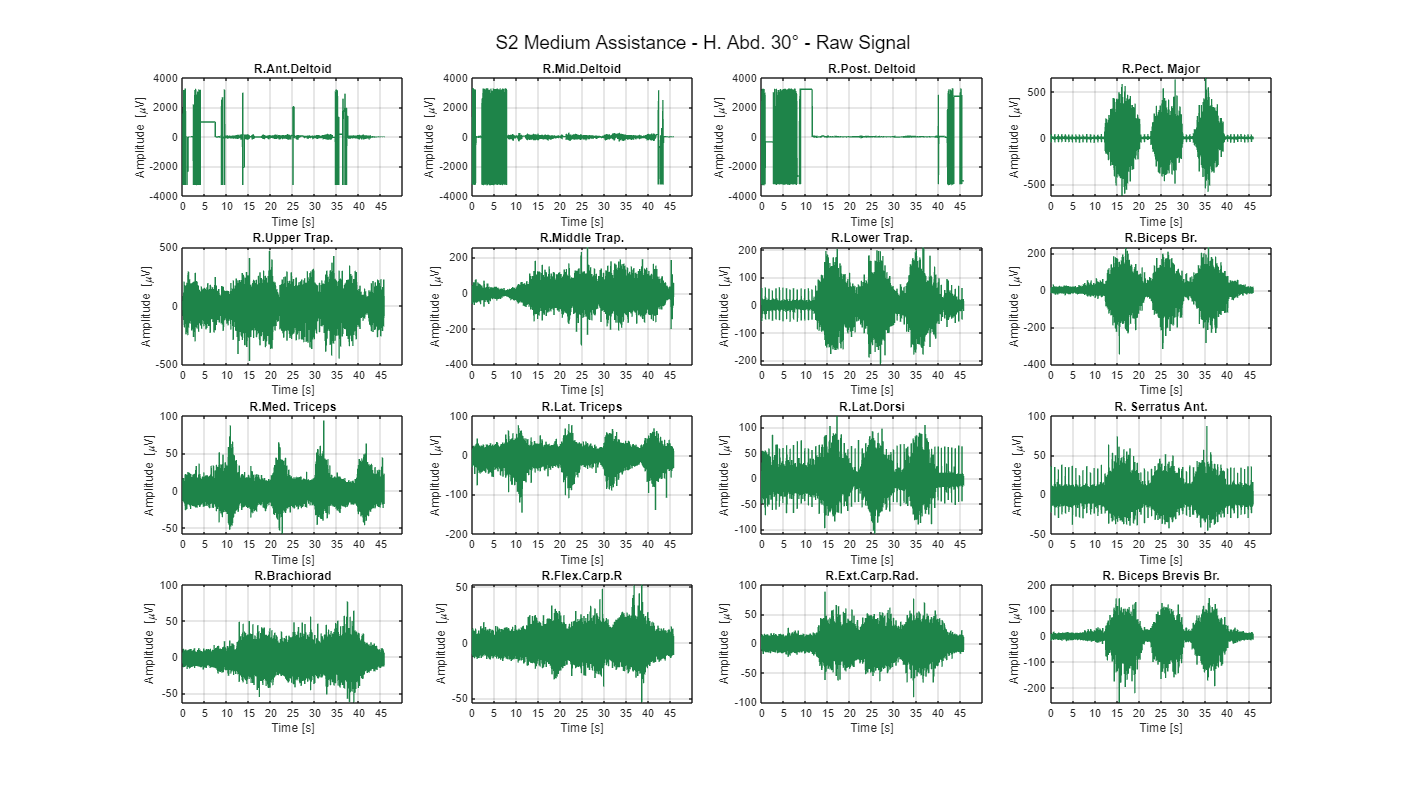

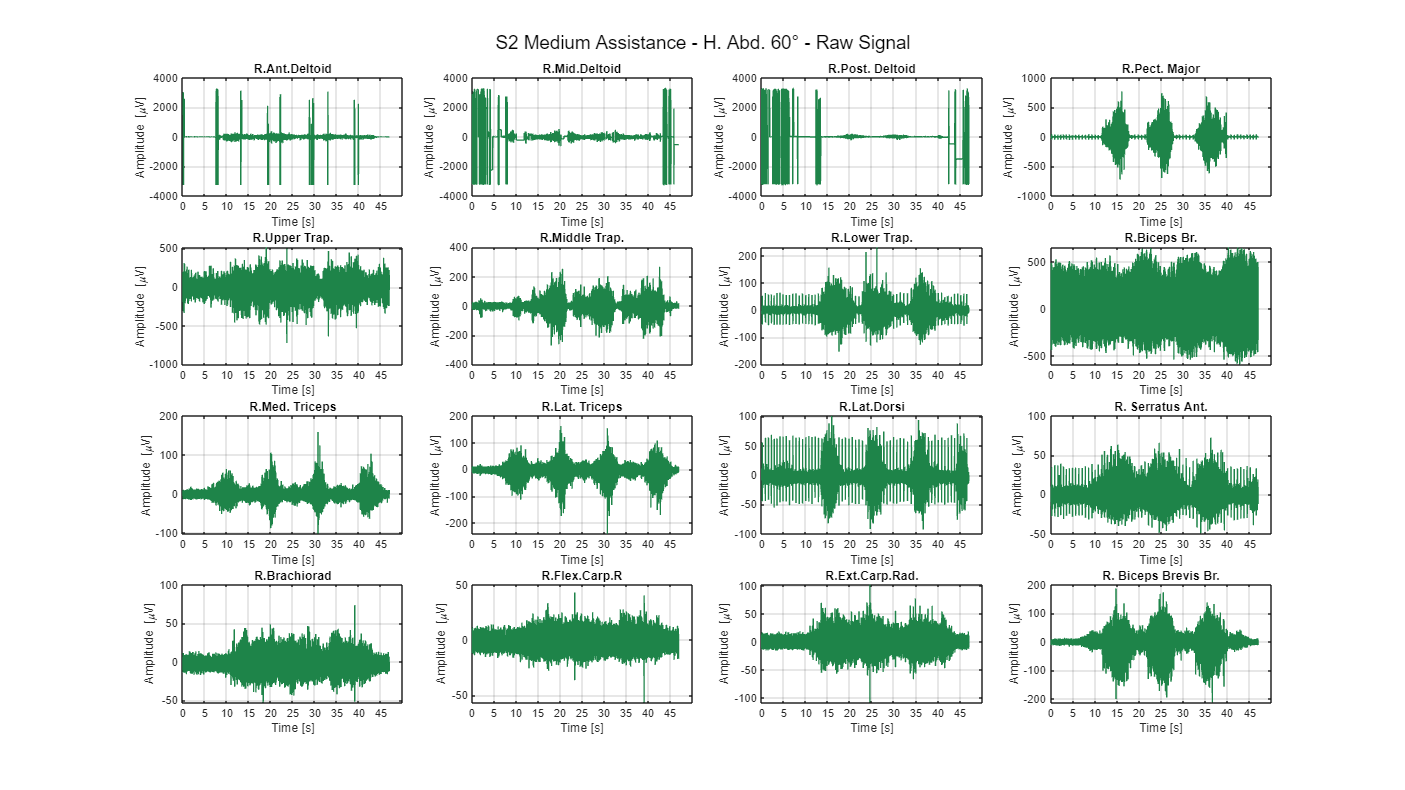

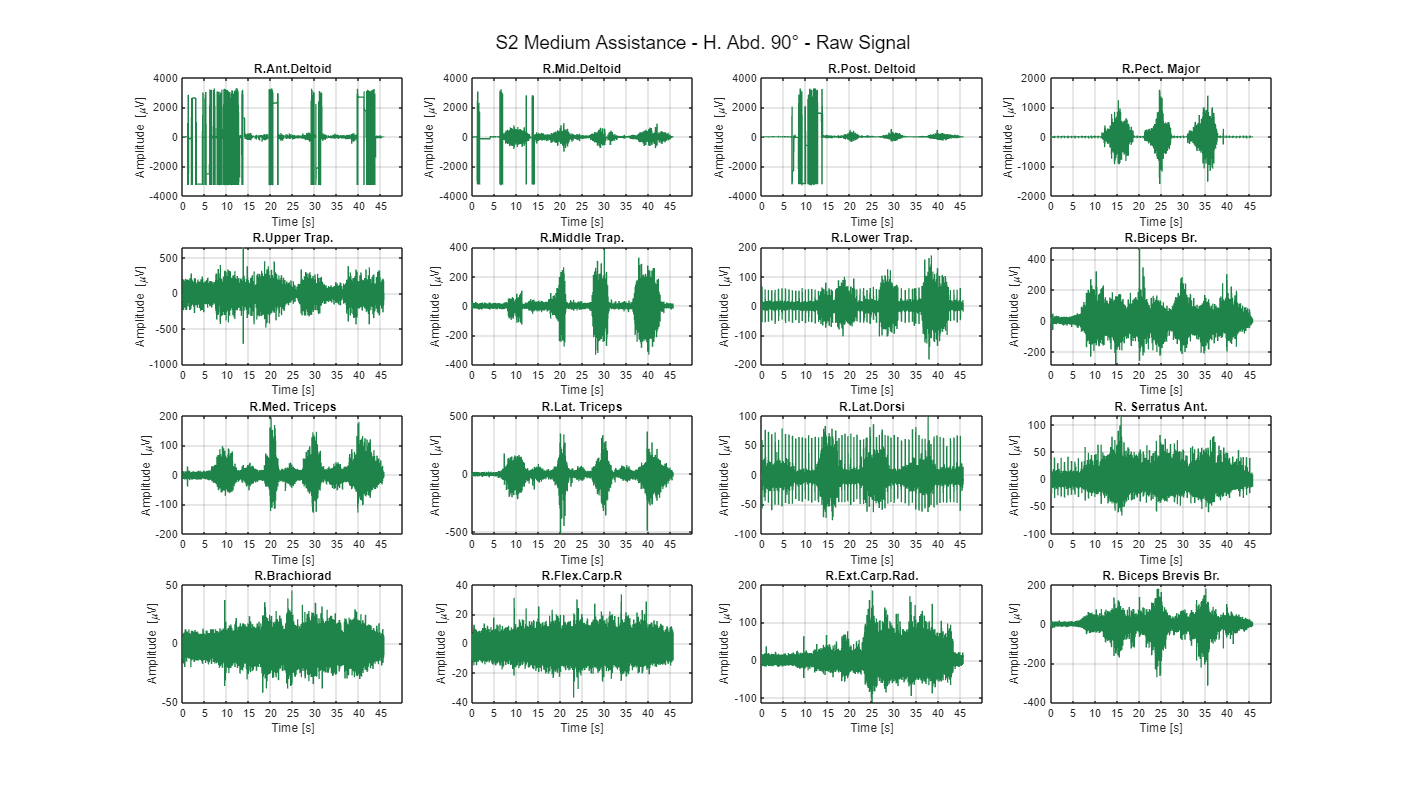

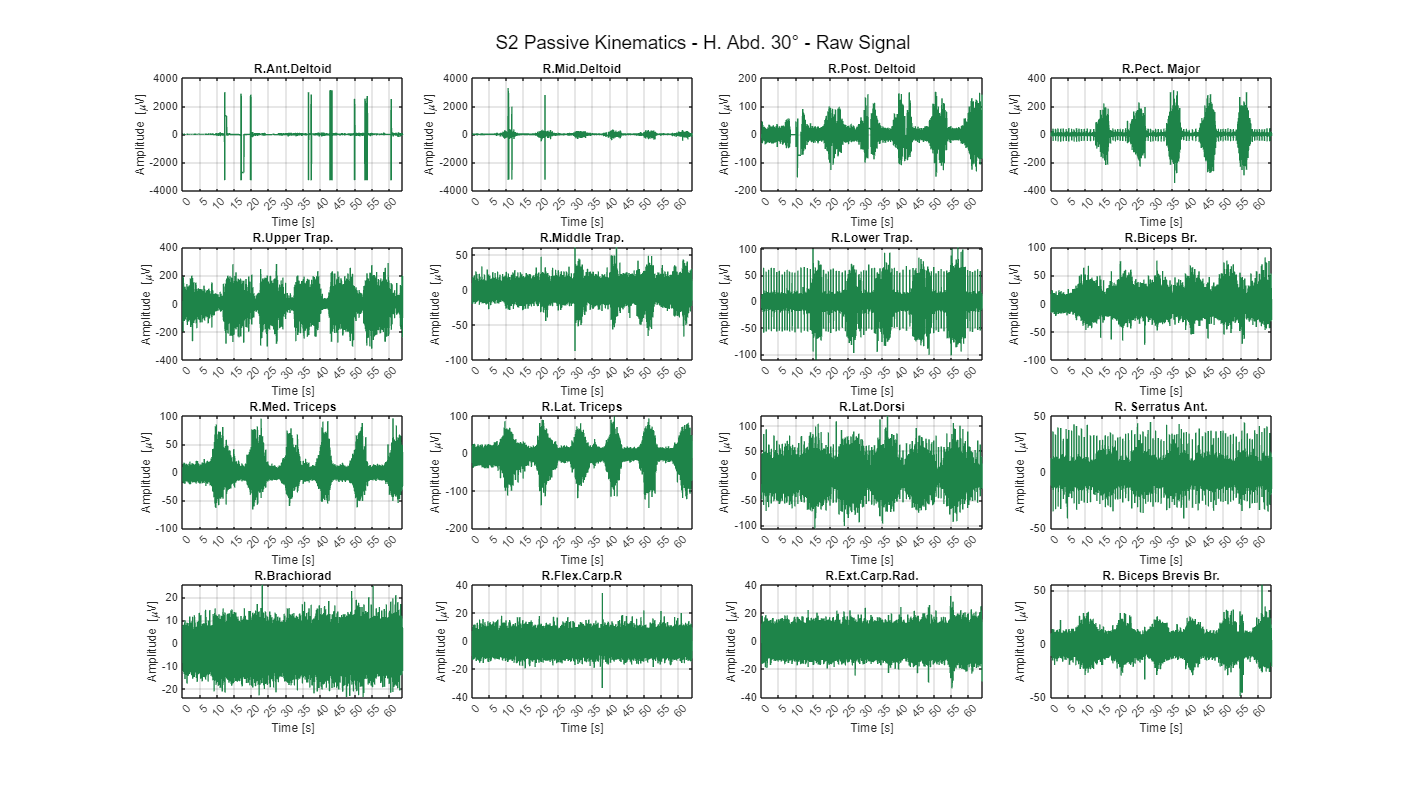

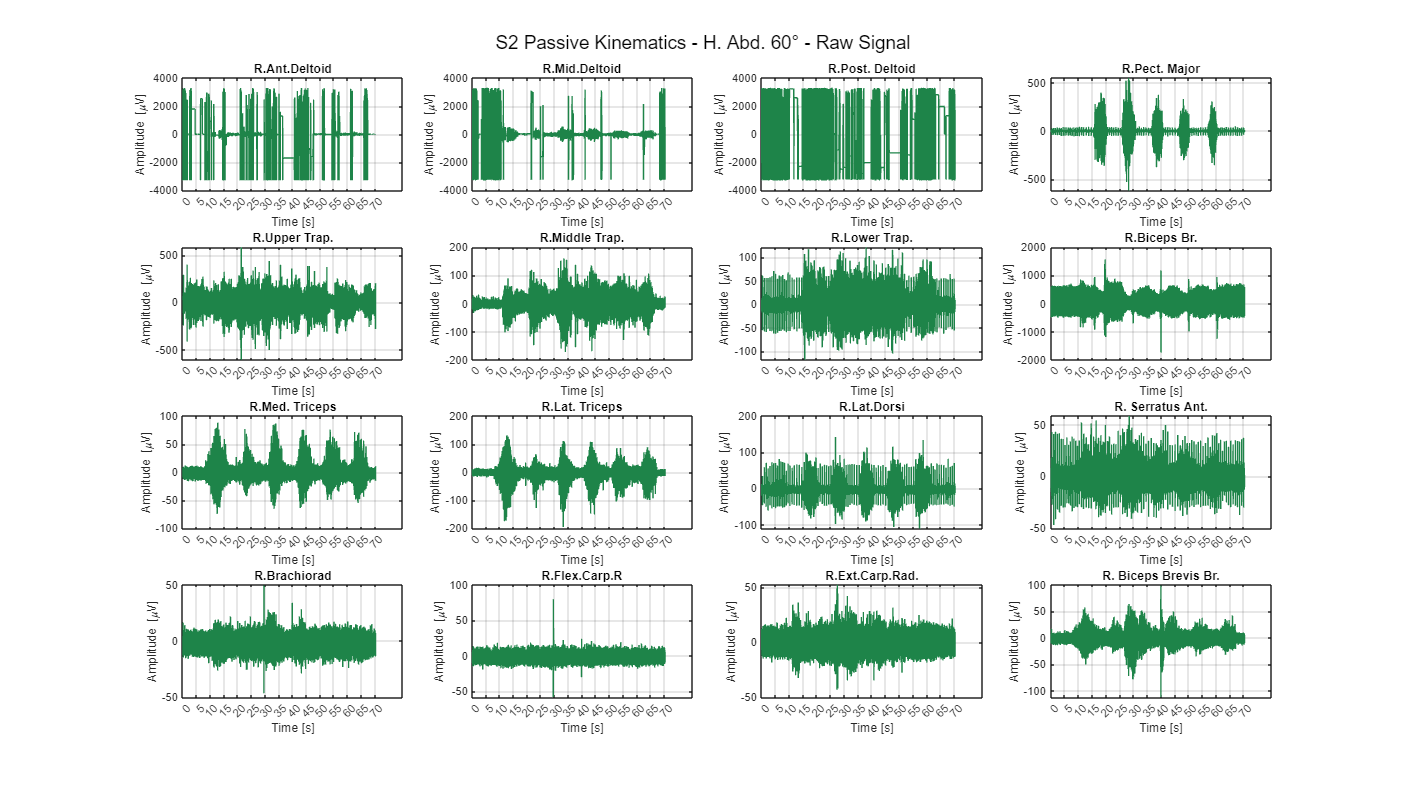

% Iterate over each condition
for c = 1:length(conditions)
    condition = conditions{c};
    conditionEng = conditionsEng{c}; % Corresponding English name
    
    % Iterate over each angle
    for a = 1:length(angles)
        angle = angles(a);
        
        % Access raw EMG data for this condition and angle
        emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
        time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;
        
        % Create an invisible figure
        fig = figure('Name', sprintf('%s - %d°', conditionEng, angle), 'NumberTitle', 'off', 'Visible', 'off');
        set(fig, 'Position', [100, 100, 1600, 900]); % Set figure size
        
        % Plot each muscle signal in a subplot
        for m = 1:numMuscles
            subplot(4, 4, m);
            plot(time, emgData{:, m}, "Color", PS.Green4);

            title(nameMuscles{m}, 'Interpreter', 'none');
            xlabel('Time [s]');
            ylabel('Amplitude [\muV]');
            grid on;

            xticks(0:5:time(end));            
        end
        
        % Add a main title for the entire figure in English
        sgtitle(sprintf('S2 %s - H. Abd. %d° - Raw Signal', conditionEng, angle));
        
        % Save the figure as an SVG file
        saveas(fig, sprintf('RawSignal_%s_Angle_%d.svg', conditionEng, angle));
        
        % Close the figure to avoid memory overload
        close(fig);
    end
end

## **FFT and PSD computation**

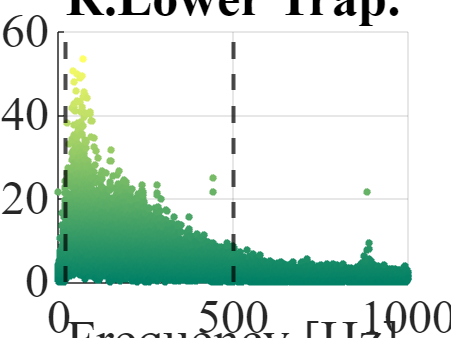

fs = 2000;

% Dimension for svg file
pect_major_muscle = 'R.Pect. Major'; % Nome muscolo di interesse
pect_major_size = [100, 100, 1800, 1400]; % Dimensioni per Pect Major
muscle_minori_size = [100, 100, 1000, 750]; % Dimensioni per muscoli minori

% Personalization of font size
common_title_fontsize = 46; 
common_label_fontsize = 40; 
common_tick_fontsize = 36;  

% Font size for Pect Major
pect_major_title_fontsize = 48; 
pect_major_label_fontsize = 44; 

angles = [30, 60, 90];

f_FFT = fs * (0:(nsamples/2)) / nsamples;

% Iterate over all the conditions
for c = 1:length(conditions)
    condition = conditions{c};
    conditionEng = conditionsEng{c};

    % Iterate over all the angles
    for a = 1:length(angles)
        angle = angles(a);

        emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
        time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;

        % Iterate over all the angles
        for m = 1:numMuscles
            % Spectrum with both teh two sides [-Fmax:+Fmax]
            p1 = fft(emgData{:,m});
            p1 = abs(p1/nsamples);

            % UInilayteral spectrum 
            p1 = p1(1:nsamples/2+1);
            p1(2:end-1) = 2*p1(2:end-1);
            p1 = p1 / (fs / nsamples); % Normalization to the frequency resolution

            % Create a fig fr each muscle
            if strcmp(nameMuscles{m}, pect_major_muscle)
                % Pectoralis Major
                fig = figure('Name', sprintf('%s - %d° - %s', conditionEng, angle, nameMuscles{m}), 'NumberTitle', 'off');
                set(fig, 'Position', pect_major_size); 
            else
                % Other muscles
                fig = figure('Name', sprintf('%s - %d° - %s', conditionEng, angle, nameMuscles{m}), 'NumberTitle', 'off');
                set(fig, 'Position', muscle_minori_size); 
            end

            % Apply the colormap 'summer'
            cmap = colormap(summer);
            numColors = size(cmap, 1);
            normalizedPSD = (p1 - min(p1)) / (max(p1) - min(p1));
            colorIndices = round(normalizedPSD * (numColors - 1)) + 1;

            % Plot PSD for each muscle
            scatter(f_FFT, p1, 30, cmap(colorIndices, :), 'filled');
            hold on;

            % Configure titles and axes
            if strcmp(nameMuscles{m}, pect_major_muscle)
                title(nameMuscles{m}, 'FontSize', pect_major_title_fontsize, 'FontWeight', 'bold', 'Interpreter', 'none');
                xlabel('Frequency [Hz]', 'FontSize', pect_major_label_fontsize, 'FontName', 'Times');
                ylabel('PSD [\muV^2/Hz]', 'FontSize', pect_major_label_fontsize, 'FontName', 'Times', 'Units', 'Normalized', 'Position', [-0.15, 0.5, 0]);
            else
                title(nameMuscles{m}, 'FontSize', common_title_fontsize, 'FontWeight', 'bold', 'Interpreter', 'none');
                xlabel('Frequency [Hz]', 'FontSize', common_label_fontsize, 'FontName', 'Times');
                ylabel('PSD [\muV^2/Hz]', 'FontSize', common_label_fontsize, 'FontName', 'Times', 'Units', 'Normalized', 'Position', [-0.15, 0.5, 0]);
            end

            set(gca, 'FontSize', common_tick_fontsize, 'FontName', 'Times');
            grid on;

            % Cutoff lines 
            xline(20, '--k', 'LineWidth', 3);
            xline(500, '--k', 'LineWidth', 3);

            saveas(fig, sprintf('PSD_%s_Angle_%d_%s.svg', conditionEng, angle, nameMuscles{m}));
            close(fig);
        end
    end
end

## **Signal Processing: Butterworth and Notch filter**

Power line interference can affect signal recording. 

Cometa sensors are not shielded against interference. Its signal was thus **filtered to avoid European power line interference (50 Hz and harmonics) **using a Hampel filter [[13](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5638457/#pone.0186132.ref013)]. (https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5638457/)

% Specific conditions and angles
specific_condition = 'Eval'; 
specific_angle = 30;

% Filters
low_cutoff = 20; 
high_cutoff = 500; 
notch_freq = 50;  
notch_bandwidth = 5;  

% Filter parameters
[b_BP, a_BP] = butter(6, [low_cutoff, high_cutoff] / (fs / 2), 'bandpass');
[d_Notch, c_Notch] = iirnotch(notch_freq / (fs / 2), notch_bandwidth / (fs / 2));

% Specific colors
raw_color = PS.DYellow4;
filtered_color = PS.Red2;

% Personalized dimensions
pect_major_muscle = 'R.Pect. Major';
pect_major_size = [100, 100, 1200, 750]; % Pect Major size
muscle_minori_size = [100, 100, 800, 700]; % Minor muscles size

% Personalized Font size
common_title_fontsize = 38; 
common_label_fontsize = 36; 
common_tick_fontsize = 32;  
common_legend_fontsize = 30;

% Data loading for the specific condition and angle
emgData = allTxtData.(specific_condition).(sprintf('Angle_%d', specific_angle)).data;
time = allTxtData.(specific_condition).(sprintf('Angle_%d', specific_angle)).time;

for m = 1:numMuscles
    muscle_name = nameMuscles{m};

    % Raw and filtered signal 
    raw_signal = emgData{:, m};
    filtered_signal = filtfilt(b_BP, a_BP, raw_signal);
    filtered_signal = filtfilt(d_Notch, c_Notch, filtered_signal);

    % Figure creation for each muscle
    if strcmp(muscle_name, pect_major_muscle)
        % Dimension for the Pect Major
        fig = figure('Name', sprintf('%s - %d° - %s', specific_condition, specific_angle, muscle_name), 'NumberTitle', 'off');
        set(fig, 'Position', pect_major_size);
    else
        % Dimension for the minor muscles
        fig = figure('Name', sprintf('%s - %d° - %s', specific_condition, specific_angle, muscle_name), 'NumberTitle', 'off');
        set(fig, 'Position', muscle_minori_size);
    end

    % Plot raw signal 
    plot(time, raw_signal, 'Color', raw_color, 'LineWidth', 1.5);
    hold on;

    % Plot filtered signal 
    plot(time, filtered_signal, 'Color', filtered_color, 'LineWidth', 1.5);

    title(muscle_name, 'Interpreter', 'none', 'FontSize', common_title_fontsize, 'FontWeight', 'bold');
    xlabel('Time [s]', 'FontSize', common_label_fontsize);
    ylabel('Amplitude [\muV]', 'FontSize', common_label_fontsize);
    set(gca, 'FontName', 'Times', 'FontSize', common_tick_fontsize); % Numeri degli assi

    xlim([0, time(end)]);
    grid on;
    legend({'Raw', 'Filtered'}, 'Location', 'northoutside', 'Orientation', 'horizontal', 'FontSize', common_legend_fontsize, 'FontName', 'Times');
    xticks(0:5:time(end));

    ax = gca; 
    ax.Position = [0.2, 0.2, 0.75, 0.55]; 

    % Save figure in svg
    saveas(fig, sprintf('Filter_%s_%s_Angle_%d.svg', muscle_name, specific_condition, specific_angle));

    % Close figure to avoid storage matters
    close(fig);
end

**RMS normalized to MVC**

RMS normalized to the MVC for the Trasnsparency condition and the 30° angle of H. Abd.

% Define parameters
window_size_ms = 300;  % Window size in milliseconds

% Convert window size to samples
window_size_samples = round(window_size_ms * fs / 1000);

% Loop only for 'Eval' condition and 30° angle
condition = 'Eval';
conditionEng = 'Transparency';
angle = 30;

% Personalized dimensions
pect_major_muscle = 'R.Pect. Major'; 
pect_major_size = [100, 100, 1300, 900]; 
muscle_minori_size = [100, 100, 900, 800]; 

% Font size
common_title_fontsize = 38; 
common_label_fontsize = 36; 
common_tick_fontsize = 32;  
common_legend_fontsize = 30; 

% Data loading
emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;        
time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;        

% Loop through muscles and plot each in a separate figure
for m = 1:numMuscles
    muscle_name = nameMuscles{m};

    % Raw EMG signal
    raw_signal = emgData{:, m};
    
    % PB Butterworth filter        
    filtered_signal = filtfilt(b_BP, a_BP, raw_signal);

    % Notch filter
    filtered_signal = filtfilt(d_Notch, c_Notch, filtered_signal);
    
    % Full wave rectification
    rec_signal = abs(filtered_signal);
    
    %% RMS envelope
    % Step 1: Square the EMG signal
    squared_signal = rec_signal.^2;
    
    % Step 2: Apply the moving average on the squared signal
    rms_moving_avg = movmean(squared_signal, window_size_samples);
    
    % Step 3: Take the square root to get the RMS envelope
    rms_envelope = sqrt(rms_moving_avg);

    % Normalization to MVC
    signal_rms_norm = rms_envelope / mvc(m);
    filtered_signal_norm = filtered_signal / mvc(m);
    
    if strcmp(muscle_name, pect_major_muscle)
        
        fig = figure('Name', sprintf('%s - %d° - %s', condition, angle, muscle_name), 'NumberTitle', 'off');
        set(fig, 'Position', pect_major_size); % Dimensioni maggiori
    else
        
        fig = figure('Name', sprintf('%s - %d° - %s', condition, angle, muscle_name), 'NumberTitle', 'off');
        set(fig, 'Position', muscle_minori_size); % Dimensioni maggiori
    end

    % Plot Norm. Filtered Signal
    plot(time, filtered_signal_norm, 'Color', PS.Green1, 'LineWidth', 1.5);
    grid on;
    hold on;

    % Plot Norm. RMS envelope
    plot(time, signal_rms_norm, 'Color', PS.DGreen5, 'LineWidth', 2);    
 
    title(muscle_name, 'Interpreter', 'none', 'FontSize', common_title_fontsize, 'FontWeight', 'bold');
    xlabel('Time [s]', 'FontSize', common_label_fontsize);
    ylabel('Norm. Amplitude []', 'FontSize', common_label_fontsize, 'FontName', 'Times', 'Interpreter', 'tex');
    set(gca, 'FontName', 'Times', 'FontSize', common_tick_fontsize);

    legend({'Norm. Filtered', 'Norm. RMS'}, 'Location', 'northoutside', 'Orientation', 'horizontal', 'FontSize', common_legend_fontsize, 'FontName', 'Times');
    xticks(0:5:time(end));
    xlim([0, time(end)]);

    ax = gca; 
    ax.Position = [0.15, 0.25, 0.75, 0.55];  

    saveas(gcf, sprintf('RMS_%s_30deg.svg', nameMuscles{m}));
    close(fig);
end

**Comparison AssMedia, ResAlta, Transp**

From now on it has been defined a window of 2000 samples to make the signal smoother.

colors = {PS.DOrange1, PS.Blue5, PS.LGreen3};

% Font size
common_title_fontsize = 42; 
common_label_fontsize = 38; 
common_tick_fontsize = 34; 
common_legend_fontsize = 34; 
other_muscles_size = [100, 100, 1200, 1000]; 
pect_major_size = [100, 100, 1600, 1300];  

% Define the specifi conditions
specificConditions = {'AssMedia', 'ResAlta', 'Eval'};
specificConditionsEng = {'Med. Ass.', 'High Res.', 'Transp.'}; % Abbreviate labels

% Definine the smoothing window (es. 2000 samples)
smoothing_window_size = 2000;

% Iterate over each condition and angle
for m = 1:numMuscles
    muscle_name = nameMuscles{m};

    fig = figure('Name', sprintf('Comparison - %d° - %s', angle, muscle_name), 'NumberTitle', 'off');
    hold on;

    % Specific font for each minor muscle
    if strcmp(muscle_name, 'R.Pect. Major')
        current_title_fontsize = common_title_fontsize; % Font size normale per Pectoralis Major
        current_label_fontsize = common_label_fontsize;
        current_tick_fontsize = common_tick_fontsize;
        current_legend_fontsize = common_legend_fontsize;
        fig_height = pect_major_size(4); % Altezza normale
    else
        current_title_fontsize = common_title_fontsize + 10; % Aumentato di 10
        current_label_fontsize = common_label_fontsize + 8;
        current_tick_fontsize = common_tick_fontsize + 8;
        current_legend_fontsize = common_legend_fontsize + 8;
        fig_height = other_muscles_size(4) + 150; % Aumenta l'altezza della figura di 150 px per muscoli minori
    end

    for c = 1:length(specificConditions)
        condition = specificConditions{c};
        
        % Access to the raw data 
        emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
        time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;
        
        % Raw EMG signal
        raw_signal = emgData{:, m};
        
        % Band Pass filter
        filtered_signal = filtfilt(b_BP, a_BP, raw_signal);

        % Apply the Notch filter
        filtered_signal = filtfilt(d_Notch, c_Notch, filtered_signal);
        
        % Full wave rectification
        rec_signal = abs(filtered_signal);
        
        % RMS envelope
        squared_signal = raw_signal.^2;
        rms_moving_avg = movmean(squared_signal, window_size_samples);
        rms_envelope = sqrt(rms_moving_avg);
        
        % Normalization to the MVC
        signal_norm = rms_envelope / mvc(m);

        % Apply moving average to make the sgnal smoother 
        signal_smooth = movmean(signal_norm, smoothing_window_size);

        % Shift for each angle and condition to make the starting position
        % uniform among the different conditions 
        if angle == 30
            if strcmp(condition, 'Eval')
                shifted_time = time - 1.8;
            elseif strcmp(condition, 'AssMedia') || strcmp(condition, 'ResAlta')
                shifted_time = time - 1.5;
            else
                shifted_time = time; 
            end
        elseif angle == 60
            if strcmp(condition, 'Eval')
                shifted_time = time - 1.8;
            else
                shifted_time = time; 
            end
        else
            shifted_time = time;
        end

        % Filter the values of time and signal to include only those ones >= 0
        valid_indices = shifted_time >= 0;
        shifted_time = shifted_time(valid_indices);
        signal_smooth = signal_smooth(valid_indices);
                
        % Plot the RMS signal normalized to the MVC
        h = plot(shifted_time, signal_smooth, 'DisplayName', specificConditionsEng{c}, 'Color', colors{c}, 'LineWidth', 4);
    end

    title(muscle_name, 'Interpreter', 'none', 'FontSize', current_title_fontsize, 'FontWeight', 'bold');
    xlabel('Time [s]', 'FontSize', current_label_fontsize);
    ylabel('Norm. RMS []', 'FontSize', current_label_fontsize, 'FontName', 'Times', 'Interpreter', 'tex');
    set(gca, 'FontName', 'Times', 'FontSize', current_tick_fontsize);

    % Vertuical lines to dived the three repetitions computed
    xline(10, '--k', 'LineWidth', 3);
    xline(20, '--k', 'LineWidth', 3);
    xline(30, '--k', 'LineWidth', 3);
    xline(40, '--k', 'LineWidth', 3);
    
    % Use trhe value y constnt for all the labels
    yLabelPos = ylim(gca);

    if strcmp(muscle_name, 'R.Brachiorad')
        labelY = yLabelPos(2) * 0.6; % Posizione più bassa per R.Brachiorad (60% del limite superiore)
    else
        labelY = yLabelPos(2) * 0.8; % Posizione normale per gli altri muscoli (80% del limite superiore)
    end

    % Add labels to the vertical lines 
    text(15, labelY, '1^{st}', 'FontSize', current_tick_fontsize, 'FontName', 'Times', ... % Aumentata
        'BackgroundColor', 'white', 'EdgeColor', 'black', 'LineWidth', 0.25, ... % Diminuito
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
    text(25, labelY, '2^{nd}', 'FontSize', current_tick_fontsize, 'FontName', 'Times', ... % Aumentata
        'BackgroundColor', 'white', 'EdgeColor', 'black', 'LineWidth', 0.25, ... % Diminuito
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
    text(35, labelY, '3^{rd}', 'FontSize', current_tick_fontsize, 'FontName', 'Times', ... % Aumentata
        'BackgroundColor', 'white', 'EdgeColor', 'black', 'LineWidth', 0.25, ... % Diminuito
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');

    lgd = legend({'Med. Ass.', 'High Res.', 'Transp.'}, 'Location', 'northoutside', 'Orientation', 'horizontal', ...
            'FontSize', current_legend_fontsize, 'FontName', 'Times', 'Box', 'on');

    if strcmp(muscle_name, 'R.Pect. Major')
        set(fig, 'Position', pect_major_size); 
    else
        set(fig, 'Position', [other_muscles_size(1), other_muscles_size(2), other_muscles_size(3), fig_height]);
    end

    % Axis position
    ax = gca; 
    ax.Position = [0.2, 0.2, 0.65, 0.6];

    % Distance of label from y-axis 
    yLabel = ylabel('Norm. RMS []', 'FontSize', current_label_fontsize, 'FontName', 'Times', 'Interpreter', 'tex');
    yLabel.Position(1) = yLabel.Position(1) - 0.25;

    grid on;
    xticks(0:5:45);
    xlim([0, 45]);
    hold off;
    
    % Save the fig in svg
    saveas(fig, sprintf('Comparison_%s_Angle_%d.svg', muscle_name, angle));
    close(fig);
end

**Assistance Levels Comparison**

Comparison between the two levels of Assistance, Low and Medium

colors = {PS.DOrange5, PS.DOrange1}; 

common_title_fontsize = 42;
common_label_fontsize = 38; 
common_tick_fontsize = 34;  
common_legend_fontsize = 34; 
other_muscles_size = [100, 100, 1200, 1000]; 
pect_major_size = [100, 100, 1600, 1300];  

specificConditions = {'AssBassa', 'AssMedia'};
specificConditionsEng = {'Low Ass.', 'Medium Ass.'};

smoothing_window_size = 2000;

% Iterate over each muscle
for m = 1:numMuscles
    muscle_name = nameMuscles{m};
    
    % Iterate over each angle
    for a = 1:length(angles)
        angle = angles(a);
        
        % Create a new fig for ecah condition and angle
        fig = figure('Name', sprintf('Assistenza - %s - Angolo %d°', muscle_name, angle), 'NumberTitle', 'off');
        
        hold on; 

        % Define a font size
        if strcmp(muscle_name, 'R.Pect. Major')
            current_title_fontsize = common_title_fontsize; 
            current_label_fontsize = common_label_fontsize;
            current_tick_fontsize = common_tick_fontsize;
            current_legend_fontsize = common_legend_fontsize;
            fig_height = pect_major_size(4); 
        else          
            current_title_fontsize = common_title_fontsize + 10; 
            current_label_fontsize = common_label_fontsize + 8;
            current_tick_fontsize = common_tick_fontsize + 8;
            current_legend_fontsize = common_legend_fontsize + 8;
            fig_height = other_muscles_size(4) + 150; 
        end

        % Iterate over each specific condition
        for c = 1:length(specificConditions)
            condition = specificConditions{c};
            
            % Accesso to the raw data
            emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
            time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;
            
            % EMG raw
            raw_signal = emgData{:, m};
            
            % PB Butterworth
            filtered_signal = filtfilt(b_BP, a_BP, raw_signal);
    
            % Notch 
            filtered_signal = filtfilt(d_Notch, c_Notch, filtered_signal);
            
            % Full wave rectification
            rec_signal = abs(filtered_signal);
            
            % RMS envelope
            squared_signal = raw_signal.^2;
            rms_moving_avg = movmean(squared_signal, window_size_samples);
            rms_envelope = sqrt(rms_moving_avg);
    
            % Normalization to the MVC
            signal_norm = rms_envelope / mvc(m);

            % Apply a moving average to make the signal smoother
            signal_smooth = movmean(signal_norm, smoothing_window_size);

            % Time shift for each angle and condition
            if angle == 30 && strcmp(condition, 'AssBassa')
                shifted_time = time - 4.5; 
            elseif angle == 30 && strcmp(condition, 'AssMedia')
                shifted_time = time - 1.8;
            elseif angle == 60 && strcmp(condition, 'AssMedia')
                shifted_time = time - 0.5;
            elseif angle == 60 && strcmp(condition, 'AssBassa')
                shifted_time = time - 2; 
            elseif angle == 90 && strcmp(condition, 'AssBassa')
                shifted_time = time - 2.1;
            else
                shifted_time = time;
            end

            % Include the only signals >= 0
            valid_indices = shifted_time >= 0;
            shifted_time = shifted_time(valid_indices);
            signal_smooth = signal_smooth(valid_indices);
                    
            % Plot the signal normilized to the MVC
            h = plot(shifted_time, signal_smooth, 'Color', colors{c}, 'LineWidth', 4, 'DisplayName', specificConditionsEng{c});
        end

        % Add vertical lines for each repetitions
        xline(10, '--k', 'LineWidth', 3);
        xline(20, '--k', 'LineWidth', 3);
        xline(30, '--k', 'LineWidth', 3);
        xline(40, '--k', 'LineWidth', 3);

        title(muscle_name, 'Interpreter', 'none', 'FontSize', current_title_fontsize, 'FontWeight', 'bold');
        xlabel('Time [s]', 'FontSize', current_label_fontsize);
        ylabel('Norm. RMS []', 'FontSize', current_label_fontsize, 'FontName', 'Times', 'Interpreter', 'tex');
        set(gca, 'FontName', 'Times', 'FontSize', current_tick_fontsize);

        % Const y-value for all the labels
        yLabelPos = ylim(gca); 
        labelY = yLabelPos(2) * 0.8; 

        % Add the labels for erach vertical line
        text(15, labelY, '1^{st}', 'FontSize', current_tick_fontsize, 'FontName', 'Times', ...
            'BackgroundColor', 'white', 'EdgeColor', 'black', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
        text(25, labelY, '2^{nd}', 'FontSize', current_tick_fontsize, 'FontName', 'Times', ...
            'BackgroundColor', 'white', 'EdgeColor', 'black', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
        text(35, labelY, '3^{rd}', 'FontSize', current_tick_fontsize, 'FontName', 'Times', ...
            'BackgroundColor', 'white', 'EdgeColor', 'black', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');

        lgd = legend({'Low Ass.', 'Medium Ass.'}, 'Location', 'northoutside', 'Orientation', 'horizontal', ...
            'FontSize', current_legend_fontsize, 'FontName', 'Times', 'Box', 'on'); 

        if strcmp(muscle_name, 'R.Pect. Major')
            set(fig, 'Position', pect_major_size);
        else
            set(fig, 'Position', [other_muscles_size(1), other_muscles_size(2), other_muscles_size(3), fig_height]);
        end
        
        ax = gca;
        ax.Position = [0.2, 0.2, 0.65, 0.6]; 

        grid on;
        xticks(0:5:45);
        xlim([0, 45]);
        
        hold off;

        % Sve the svg
        saveas(fig, sprintf('Ass_%s_Angle%d.svg', muscle_name, angle));
        close(fig);
    end
end

**Resistance Levels Comparison**

Comparison among the three different levels of Resistance: Low, Medium, and High.

% Define the specific conditions
specificConditions = {'ResBassa', 'ResMedia', 'ResAlta'};
specificConditionsEng = {'Low Res.', 'Medium Res.', 'High Res.'};
colors = {PS.Blue1, PS.Blue3, PS.Blue5};

% Dimensions of the personalized font
common_title_fontsize = 42; 
common_label_fontsize = 38;
common_tick_fontsize = 34; 
common_legend_fontsize = 34; 
other_muscles_size = [100, 100, 1200, 1000]; 
pect_major_size = [100, 100, 1600, 1300]; 

% Define the smoothing window (es. 2000 samples)
smoothing_window_size = 2000;

% Iteratre over each muscle
for m = 1:numMuscles
    muscle_name = nameMuscles{m};
    
    % Iterate over each angle
    for a = 1:length(angles)
        angle = angles(a);
        
        % Save only the 30° angle
        if angle ~= 30
            continue; % Skip if the angle is not 30°
        end
     
        fig = figure('Name', sprintf('Res - %s - Angle %d°', muscle_name, angle), 'NumberTitle', 'off', 'Visible', 'off');
        hold on; 

        % Iterate over each specific condition
        for c = 1:length(specificConditions)
            condition = specificConditions{c};
            
            % Access raw data
            emgData = allTxtData.(condition).(sprintf('Angle_%d', angle)).data;
            time = allTxtData.(condition).(sprintf('Angle_%d', angle)).time;
            
            % Raw data
            raw_signal = emgData{:, m};
            
            % PB Butterworth
            filtered_signal = filtfilt(b_BP, a_BP, raw_signal);
    
            % Notch
            filtered_signal = filtfilt(d_Notch, c_Notch, filtered_signal);
            
            % Full wave rectification
            rec_signal = abs(filtered_signal);
            
            % RMS envelope
            squared_signal = raw_signal.^2;
            rms_moving_avg = movmean(squared_signal, window_size_samples);
            rms_envelope = sqrt(rms_moving_avg);
    
            % Normalization to the MVC
            signal_norm = rms_envelope / mvc(m);

            % Apply a moving average to make the signal smoother 
            signal_smooth = movmean(signal_norm, smoothing_window_size);

            % Time shift to align all the three repetitions
            if strcmp(condition, 'ResAlta')
                shifted_time = time - 1.5; 
            elseif strcmp(condition, 'ResBassa')
                shifted_time = time - 1;
            elseif strcmp(condition, 'ResMedia')
                shifted_time = time - 2;
            else
                shifted_time = time;
            end

            % Filter the time and signal values to include only those ones >= 0
            valid_indices = shifted_time >= 0;
            shifted_time = shifted_time(valid_indices);
            signal_smooth = signal_smooth(valid_indices);
                    
            % Plot the RMS normalized to the MVC
            h = plot(shifted_time, signal_smooth, 'Color', colors{c}, 'LineWidth', 2, 'DisplayName', specificConditionsEng{c});
        end

        % Add vertical lines for dividing the three repetitions
        xline(10, '--k', 'LineWidth', 3);
        xline(20, '--k', 'LineWidth', 3);
        xline(30, '--k', 'LineWidth', 3);
        xline(40, '--k', 'LineWidth', 3);

        title(muscle_name, 'Interpreter', 'none', 'FontSize', current_title_fontsize, 'FontWeight', 'bold');
        xlabel('Time [s]', 'FontSize', current_label_fontsize);
        ylabel('Norm. RMS []', 'FontSize', current_label_fontsize, 'FontName', 'Times', 'Interpreter', 'tex');
        set(gca, 'FontName', 'Times', 'FontSize', current_tick_fontsize);

        % Use a cont y value for all the labels 
        yLabelPos = ylim(gca);
        labelY = yLabelPos(2) * 0.8;

        % Add the labels to all the vertical lines 
        text(15, labelY, '1^{st}', 'FontSize', current_tick_fontsize, 'FontName', 'Times', ...
            'BackgroundColor', 'white', 'EdgeColor', 'black', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
        text(25, labelY, '2^{nd}', 'FontSize', current_tick_fontsize, 'FontName', 'Times', ...
            'BackgroundColor', 'white', 'EdgeColor', 'black', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
        text(35, labelY, '3^{rd}', 'FontSize', current_tick_fontsize, 'FontName', 'Times', ...
            'BackgroundColor', 'white', 'EdgeColor', 'black', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');

        lgd = legend({'Low Res.', 'Medium Res.', 'High Res.'}, 'Location', 'northoutside', 'Orientation', 'horizontal', ...
            'FontSize', current_legend_fontsize, 'FontName', 'Times', 'Box', 'on'); 

        % Fig dimensions
        if strcmp(muscle_name, 'R.Pect. Major')
            set(fig, 'Position', pect_major_size); 
        else           
            set(fig, 'Position', [other_muscles_size(1), other_muscles_size(2), other_muscles_size(3), fig_height]);
        end
        
        % Axis position
        ax = gca; 
        ax.Position = [0.2, 0.2, 0.65, 0.6]; 

        grid on;
        xticks(0:5:45); 
        xlim([0, 45]);
        
        hold off;     
                                    
        % Save th fig in svg
        saveas(gcf, sprintf('Res_%s_Angle%d.svg', muscle_name, angle));
        close(fig);
    end
end